# Natural Resources Management

# Final Project

addpath("utils\")

Dataset: **5. Jochenstein**

## Part 0. Data pre-processing

file = readmatrix("data\5. Jochenstein.csv");
data_precipitation = file(:,4); % [mm/d]
data_streamflow = file(:,5); % [m3/s]
data_temperature = file(:,6); % °C

### Dataset times

Total dataset total years and years used for training, taking 70% of the dataset

T = 365;
tr_length = 0.70;
years_total = length(file) / T

years_total = 27

years_tr = floor(years_total*tr_length)

years_tr = 18

### Dataset partition 

% Training dataset
x_tr = data_streamflow(1:T*years_tr);
u_tr = [data_precipitation(1:T*years_tr) data_temperature(1:T*years_tr)];
% Validation dataset
x_val = data_streamflow(T*years_tr+1:end);
u_val = [data_precipitation(T*years_tr+1:end) data_temperature(T*years_tr+1:end)];

### Cyclostationary  analysis

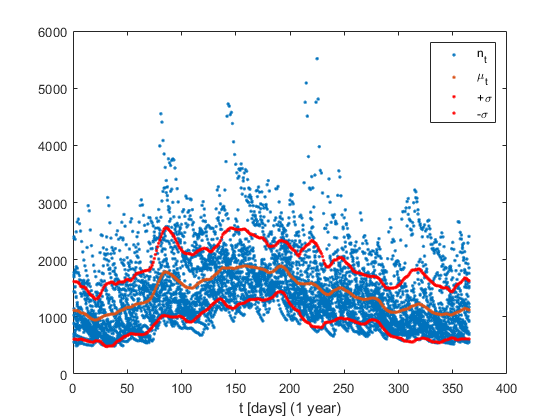

f = 5; 
N_tr = length(x_tr);
tt = repmat([1:T]', N_tr/T, 1);
% Moving Average
[mi, m] = moving_average(x_tr, T, f);
% Moving variance
[ma_var2, s2] = moving_average((x_tr - m).^2, T, f);
ma_var = ma_var2.^(1/2);
s = s2.^(1/2);
figure;
plot(tt, [x_tr, m], '.');
xlabel('t [days] (1 year)');
hold on;
% plot([1 : T], mi, 'g', 'LineWidth',.5);
plot(tt, m + s, '.r');
plot(tt, m - s, '.r');
legend('n_t', '\mu_t', '+\sigma', '-\sigma');

% legend('n_t', '\mu_t', '\mu_{cyclo}', '+\sigma', '-\sigma');

### Correlations

#### Streamflow - Precipitations

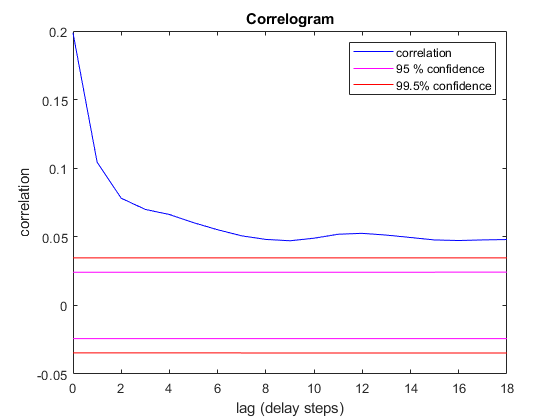

figure; correlogram(x_tr, u_tr(:,1), years_tr)

#### Streamflow - Temperature

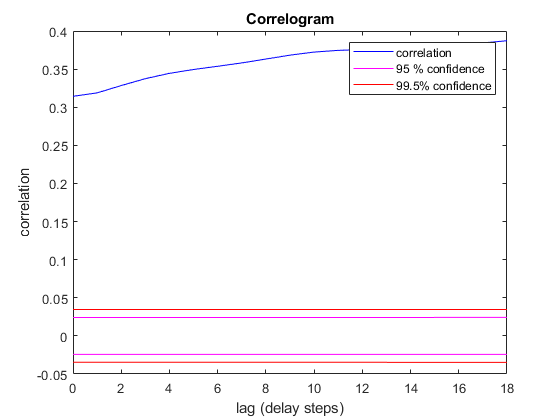

figure; correlogram(x_tr, u_tr(:,2), years_tr)

### Data normalization

f = 5; 
[x_norm, mean_x, sigma_x] = deseasonalize(x_tr, T, f);
[u_norm(:,1), mean_u(:,1), sigma_u(:,1)] = deseasonalize(u_tr(:,1), T, f);
[u_norm(:,2), mean_u(:,2), sigma_u(:,2)] = deseasonalize(u_tr(:,2), T, f);

[x_norm_val, mean_x_val, sigma_x_val] = deseasonalize(x_val, T, f);
[u_norm_val(:,1), mean_u_val(:,1), sigma_u_val(:,1)] = deseasonalize(u_val(:,1), T, f);
[u_norm_val(:,2), mean_u_val(:,2), sigma_u_val(:,2)] = deseasonalize(u_val(:,2), T, f);

### Correlations

#### Streamflow - Precipitations

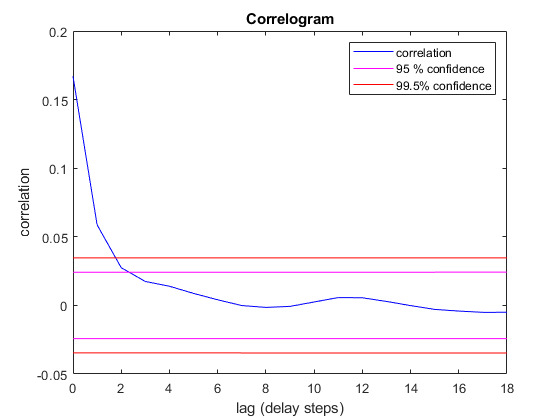

figure; correlogram(x_norm, u_norm(:,1), years_tr)

#### Streamflow - Temperature

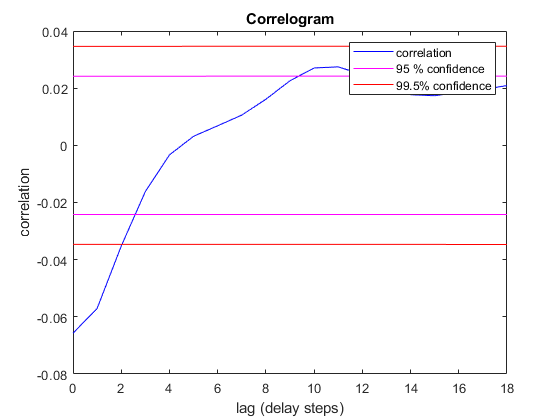

figure; correlogram(x_norm, u_norm(:,2), years_tr)

## Part 1. 1-day ahead forecast model

### Linear models

#### AR (n)

To find the best AR(n) model possible, the R2 index is evaluated for each model.

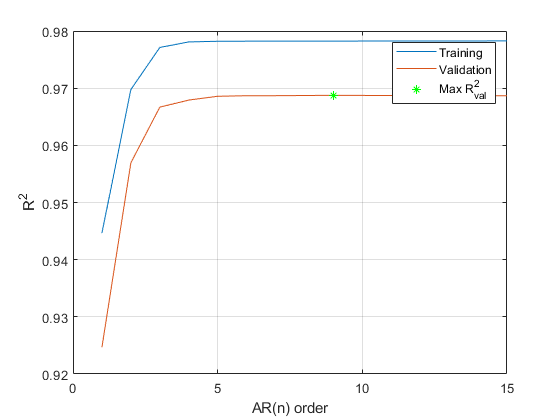

ar_iteation = 15;
r2_ar = nan(ar_iteation,1);
r2_ar_val = nan(ar_iteation,1);
r2_ar_val_max = 0;
ar_opt_idx = 0;
for i=1:ar_iteation
    [theta_ar_i, x_norm_ar] = trainAR(x_norm, i);
    x_norm_ar_val = estimateAR(x_norm_val, theta_ar_i, i);
    
%     Training
    r2_ar(i) = getR2Performance( ...
            x_tr, ...
            x_norm_ar, ...
            mean_x, ...
            sigma_x ...
        );
%     Validation
    r2_ar_val(i) = getR2Performance( ...
            x_val, ...
            x_norm_ar_val, ...
            mean_x_val, ...
            sigma_x_val ...
        );
    
    if r2_ar_val_max < r2_ar_val(i)
        theta_ar = theta_ar_i;
        ar_opt_idx = i;
        r2_ar_val_max = r2_ar_val(i);
    end
    
end
clear i
figure;
plot([r2_ar, r2_ar_val])
hold on 
plot (ar_opt_idx, r2_ar_val_max, '*g')
legend('Training','Validation','Max R^2_{val}')
xlabel('AR(n) order');ylabel('R^2');
grid on

#### Proper ARX (1,1)

y = x_norm(2:end);
M = [x_norm(1:end-1), u_norm(1:end-1,:)];
theta = M\y;
x_est = [x_norm(1); M*theta];
r2_arx = getR2Performance(x_tr, x_est, mean_x, sigma_x)

r2_arx = 0.9708

M_val = [x_norm_val(1:end-1), u_norm_val(1:end-1,:)];
x_est = [x_norm_val(1); M_val*theta];
r2_arx_val = getR2Performance(x_val, x_est, mean_x_val, sigma_x_val)

r2_arx_val = 0.9626

#### Improper ARX (1,1)

y = x_norm(2:end);
M = [x_norm(1:end-1), u_norm(2:end,:)];
theta = M\y;
x_est = [x_norm(1); M*theta];
r2_arx_imp = getR2Performance(x_tr, x_est, mean_x, sigma_x)

r2_arx_imp = 0.9563

M_val = [x_norm_val(1:end-1), u_norm_val(1:end-1,:)];
x_est = [x_norm_val(1); M_val*theta];
r2_arx_imp_val = getR2Performance(x_val, x_est, mean_x_val, sigma_x_val)

r2_arx_imp_val = 0.9545

### Nonlinear models

#### Proper ANN

The model used is an ANN with 3 neurons, iterated 10 times to find the best model possible.

% Train dataset
x_ann = [x_norm(1:end-1), u_norm(1:end-1,:)]';
y_ann = x_norm(2:end)';
% Validation dataset
x_ann_val = [x_norm_val(1:end-1) u_norm_val(1:end-1,:)]';

N_runs = 10;
r2_ann_prop = zeros(N_runs, 1);
r2_ann_prop_val = zeros(N_runs, 1);
ann_opt_idx = 0;
for i = 1:N_runs
    % ANN Train
    ann_prop_i = feedforwardnet(3);
    ann_prop_i = train(ann_prop_i,x_ann,y_ann);
    
    % view(ann_prop)
    y = ann_prop_i(x_ann);
    y_ann_prop = [x_norm(1); y'];
    r2_ann_prop(i) = getR2Performance(x_tr, y_ann_prop, mean_x, sigma_x);
    
    % Validation
    y = ann_prop_i(x_ann_val);
    y_ann_prop_val = [x_norm_val(1); y'];
    r2_ann_prop_val(i) = getR2Performance(x_val, y_ann_prop_val, mean_x_val, sigma_x_val);
    
    
    if r2_ann_prop_val(i) >= max(r2_ann_prop_val)
        ann_prop = ann_prop_i; % Optimal ANN wrt validation dataset
        ann_opt_idx = i;
    end
    
end


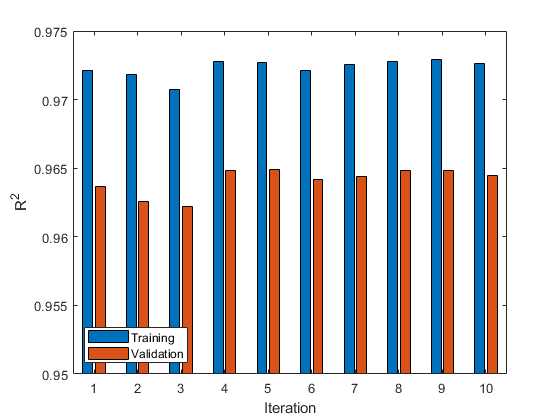

figure; 
h = bar([r2_ann_prop, r2_ann_prop_val], 'BaseValue',0.95);
set(h, {'DisplayName'}, {'Training','Validation'}')
xlabel('Iteration');ylabel('R^2');
legend('location','southwest')

#### Improper ANN

% Train dataset
x_ann = [x_norm(1:end-1), u_norm(2:end,:)]';
y_ann = x_norm(2:end)';
% Validation dataset
x_ann_val = [x_norm_val(1:end-1) u_norm_val(1:end-1,:)]';

N_runs = 10;
r2_ann_improp = zeros(N_runs, 1);
r2_ann_improp_val = zeros(N_runs, 1);
ann_improp_opt_idx = 0;
for i = 1:N_runs
    % ANN Train
    ann_improp_i = feedforwardnet(3);
    ann_improp_i = train(ann_improp_i,x_ann,y_ann);
    
    % view(ann_prop)
    y = ann_improp_i(x_ann);
    y_ann_improp = [x_norm(1); y'];
    r2_ann_improp(i) = getR2Performance(x_tr, y_ann_improp, mean_x, sigma_x);
    
    % Validation
    y = ann_improp_i(x_ann_val);
    y_ann_improp_val = [x_norm_val(1); y'];
    r2_ann_improp_val(i) = getR2Performance(x_val, y_ann_improp_val, mean_x_val, sigma_x_val);
    
    
    if r2_ann_improp_val(i) >= max(r2_ann_improp_val)
        ann_improp = ann_improp_i; % Optimal ANN wrt validation dataset
        ann_improp_opt_idx = i;
    end
    
end


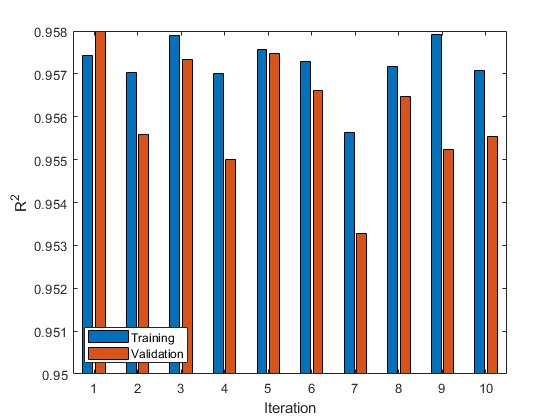

figure; 
h = bar([r2_ann_improp, r2_ann_improp_val],'BaseValue',0.95);
set(h, {'DisplayName'}, {'Training','Validation'}')
xlabel('Iteration');ylabel('R^2');
legend('location','southwest')

#### CART

The leaf size is iterated between 1 and 40 to find the optimal leaf size

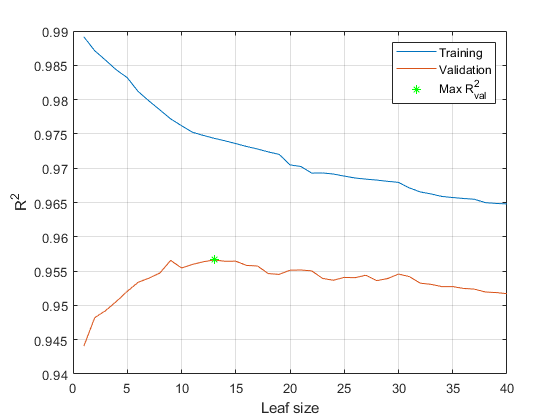

x_cart = [x_norm(1:end-1), u_norm(1:end-1,:)];
y_cart = x_norm(2:end);

x_cart_val = [x_norm_val(1:end-1), u_norm_val(1:end-1,:)];
y_cart_val = x_norm_val(2:end);
    
max_leaf_size = 40;
r2_cart = zeros(max_leaf_size,1);
r2_cart_val = zeros(max_leaf_size,1);
leafsize_opt = 0;

for i = 1:max_leaf_size
    T_i = fitrtree(x_cart, y_cart,'MinLeafSize',i);
    % view(T, 'mode', 'graph');
    y = predict(T_i, x_cart);
    y_cart_predict = [x_norm(1); y];
    r2_cart(i) = getR2Performance(x_tr, y_cart_predict, mean_x, sigma_x);
    
%     Validation
    y = predict(T_i, x_cart_val);
    y_cart_predict_val = [x_norm_val(1); y];
    r2_cart_val(i) = getR2Performance(x_val, y_cart_predict_val, mean_x_val, sigma_x_val);
    
    if r2_cart_val(i) >= max(r2_cart_val)
        T_opt = T_i; % Optimal ANN wrt validation dataset
        leafsize_opt = i;
    end 
end

figure;
plot([r2_cart, r2_cart_val])
hold on
plot (leafsize_opt, r2_cart_val(leafsize_opt), '*g')
legend('Training','Validation','Max R^2_{val}')
xlabel('Leaf size');ylabel('R^2');
grid on

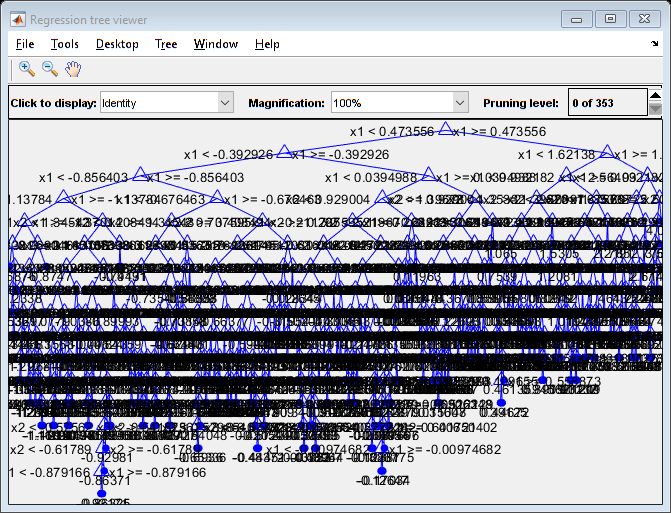

view(T_opt,'mode','graph')

T_opt.NumNodes

ans = 787

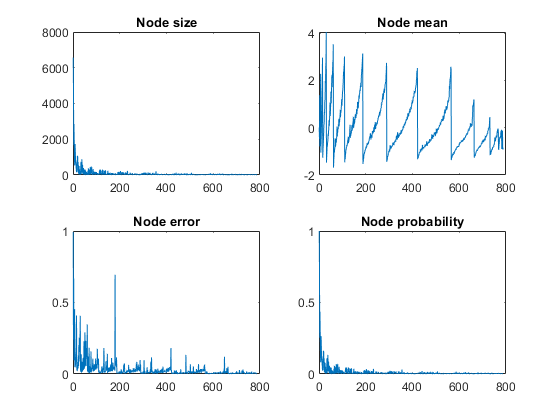

figure
subplot(2,2,1); plot( T_opt.NodeSize ); title('Node size'); % number of samples per node
subplot(2,2,2); plot( T_opt.NodeMean ); title('Node mean'); % mean samples in each node
subplot(2,2,3); plot( T_opt.NodeError ); title('Node error'); % node error
subplot(2,2,4); plot( T_opt.NodeProbability); title('Node probability')

Then is compared with the algorithm that finds the optimal solution by a smart search of params

|======================================================================================|
| Iter | Eval   | Objective:  | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize |
|      | result | log(1+loss) | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|    1 | Best   |    0.045796 |       1.578 |    0.045796 |    0.045796 |           49 |


|    2 | Accept |    0.082742 |     0.23457 |    0.045796 |    0.055443 |          290 |


|    3 | Accept |     0.26024 |    0.099274 |    0.045796 |    0.058756 |         1726 |


|    4 | Accept |    0.048311 |     0.56448 |    0.045796 |    0.062831 |            1 |


|    5 | Accept |    0.047194 |     0.36856 |    0.045796 |    0.045852 |           57 |


|    6 | Best   |    0.042079 |     0.29683 |    0.042079 |    0.042077 |            6 |


|    7 | Best   |    0.039908 |     0.13328 |    0.039908 |    0.039927 |           15 |


|    8 | Accept |     0.04603 |     0.41679 |    0.039908 |    0.039941 |            2 |


|    9 | Best   |     0.03952 |     0.16337 |     0.03952 |     0.03968 |           12 |


|   10 | Accept |     0.03952 |     0.12706 |     0.03952 |    0.039616 |           12 |


|   11 | Accept |     0.03952 |     0.12897 |     0.03952 |    0.039587 |           12 |


|   12 | Accept |     0.03952 |     0.16261 |     0.03952 |    0.039571 |           12 |


|   13 | Accept |    0.039908 |     0.11949 |     0.03952 |    0.039579 |           15 |


|   14 | Accept |    0.040227 |     0.13336 |     0.03952 |    0.039688 |           11 |


|   15 | Accept |    0.056967 |     0.12054 |     0.03952 |    0.039694 |          136 |


|   16 | Accept |    0.043034 |     0.48942 |     0.03952 |     0.03971 |            4 |


|   17 | Accept |     0.68927 |    0.089964 |     0.03952 |    0.039642 |         3283 |


|   18 | Accept |     0.18793 |    0.071138 |     0.03952 |    0.039569 |          691 |


|   19 | Accept |    0.040817 |    0.098896 |     0.03952 |    0.039595 |           26 |


|   20 | Accept |    0.040079 |     0.12149 |     0.03952 |    0.039613 |           21 |


|======================================================================================|
| Iter | Eval   | Objective:  | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize |
|      | result | log(1+loss) | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|   21 | Accept |    0.041205 |     0.15184 |     0.03952 |    0.039615 |            9 |


|   22 | Accept |    0.039741 |     0.12163 |     0.03952 |    0.039625 |           18 |


|   23 | Accept |    0.041227 |     0.15722 |     0.03952 |    0.039627 |           30 |


|   24 | Accept |    0.039848 |     0.12096 |     0.03952 |    0.039643 |           14 |


|   25 | Accept |    0.039741 |     0.18187 |     0.03952 |    0.039645 |           18 |


|   26 | Accept |    0.044053 |     0.34635 |     0.03952 |     0.03965 |            3 |


|   27 | Accept |     0.03986 |     0.14181 |     0.03952 |     0.03968 |           13 |


|   28 | Accept |    0.040158 |     0.10195 |     0.03952 |     0.03968 |           22 |


|   29 | Accept |     0.20689 |    0.064983 |     0.03952 |    0.039679 |         1050 |


|   30 | Accept |    0.052701 |    0.083646 |     0.03952 |    0.039682 |           93 |


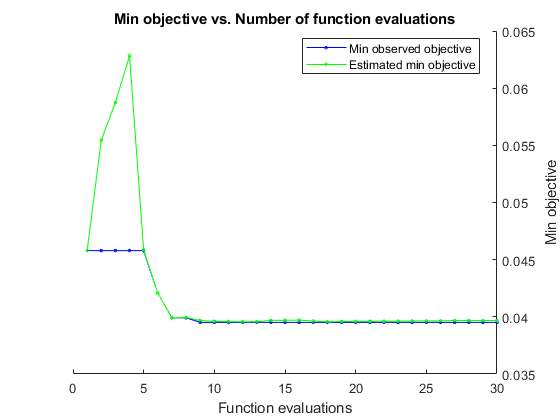

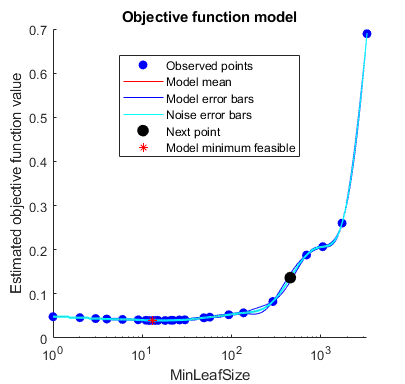


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 45.7435 seconds.
Total objective function evaluation time: 6.9904

Best observed feasible point:
    MinLeafSize
    ___________

        12     

Observed objective function value = 0.03952
Estimated objective function value = 0.039682
Function evaluation time = 0.16337

Best estimated feasible point (according to models):
    MinLeafSize
    ___________

        12     

Estimated objective function value = 0.039682
Estimated function evaluation time = 0.14232



T_opt_auto = fitrtree(x_cart, y_cart,'OptimizeHyperparameters','auto');

y = predict(T_opt_auto, x_cart_val);
y_cart_predict_val = [x_norm_val(1); y];
r2_cart_auto_val = getR2Performance(x_val, y_cart_predict_val, mean_x_val, sigma_x_val)

r2_cart_auto_val = 0.9564

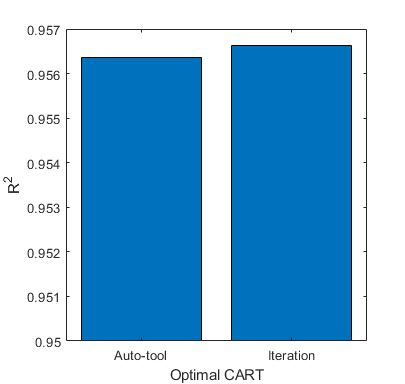

c = categorical({'Iteration','Auto-tool'});
bar(c, [max(r2_cart_val); r2_cart_auto_val],'BaseValue',0.95)
xlabel('Optimal CART');ylabel('R^2');

### Models comparison

figure;
c = categorical({ ...
    'AR(1)', ...
    'AR(opt)', ...
    'ARX(1,1) Proper', ...
    'ARX(1,1) Improper', ...
    'ANN(3) Proper', ...
    'ANN(3) Improper', ...
    'CART', ...
    });

The result is that the model with the best performance (r2=0.968) is the AR(9), but a simper model as the ARX(1,1) (r2=0.962) gives almost the same, then the most suitable to implement is this one. It can be improved looking for more complex models. At the same time, the proper ANN(3) has a good performance, it can be improved adding more neurons, but taking the risk of overfitting.

r2_index = [ ...
    r2_ar(1), r2_ar_val(1); ...
    r2_ar(ar_opt_idx), r2_ar_val(ar_opt_idx); ...
    r2_arx, r2_arx_val; ...
    r2_arx_imp, r2_arx_imp_val; ...
    r2_ann_prop(ann_opt_idx), r2_ann_prop_val(ann_opt_idx); ...
    r2_ann_improp(ann_improp_opt_idx), r2_ann_improp_val(ann_improp_opt_idx); ...
    r2_cart(leafsize_opt), r2_cart_val(leafsize_opt); ...
    ]

r2_index =     0.9446    0.9247
    0.9782    0.9688
    0.9708    0.9626
    0.9563    0.9545
    0.9727    0.9649
    0.9574    0.9580
    0.9744    0.9566


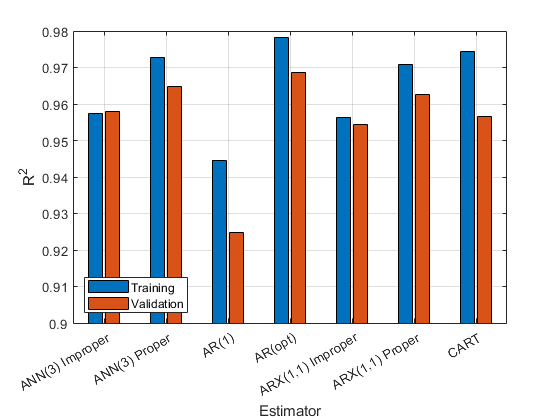

% latex(sym(r2_index))
h = bar(c,r2_index,'BaseValue',0.9);
set(h, {'DisplayName'}, {'Training','Validation'}')
xlabel('Estimator');ylabel('R^2');
legend("Location","southwest")
grid on

## Part 2. Damming policies

### Dam sizing

% years_total = 27;
lake_surface = 76984.120000e6; % [m2]
Q_month = dailyToMonthly(data_streamflow, years_total);
% https://www.hausamstrom.de/wp-content/uploads/2018/12/Folder_EnergieerlebnisJochenstein-eng.pdf

TODO: Target release

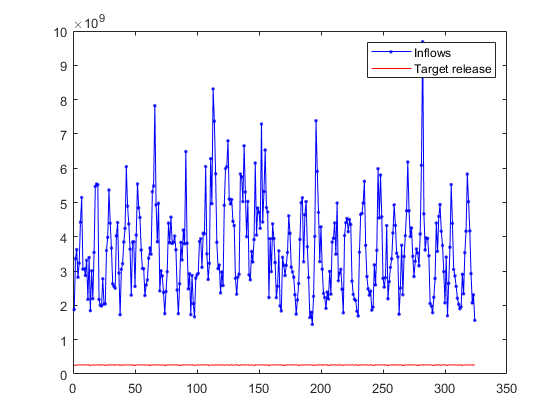

w = 100; % [m3/s] Target release - Downstrem demand 
deltaT = 3600*24*[31 28 31 30 31 30 31 31 30 31 30 31]';
Q = Q_month(:).*repmat(deltaT,years_total,1) ; % [m3/month]
W = w*ones(size(Q)).*repmat(deltaT,years_total,1) ; % [m3/month]

figure;
plot(Q, '.-b'); hold on
plot(W, 'r');
legend('Inflows', 'Target release')

#### Rippl criteria

[rippl] = abs(getRipple(W,Q));
rippl/lake_surface

ans = 0.0209

#### Sequent Peak Analysis criteria

[spa, K] = getSPA(W,Q);
spa/lake_surface

ans = 0

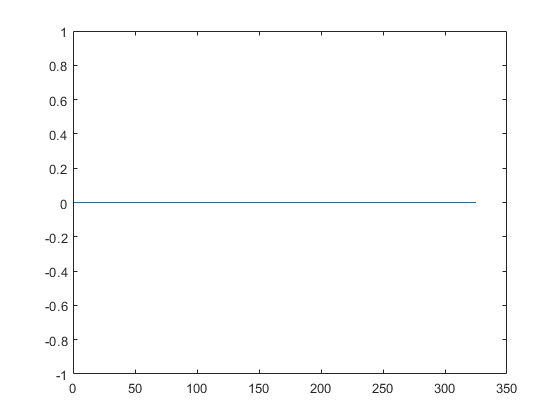

figure;
plot(K)

### Define Standard Operating policy

TODO: How to define the max release possible wrt the height?

One alternative is to use the value up to the mean + one standard deviation.

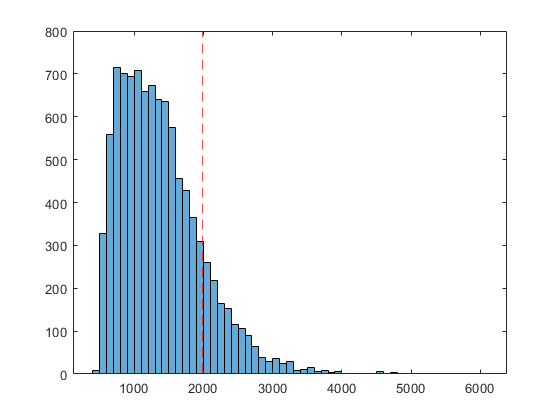

% max_nat_release_est = 3000;
max_nat_release_est = round(mean(data_streamflow) + std(data_streamflow), 3, 'significant'); % [m3/s]
figure;
histogram(data_streamflow)
hold on;
xline(max_nat_release_est,'--r');

TODO: Where can be found the suitable parameters for the lake, to determine the natural release

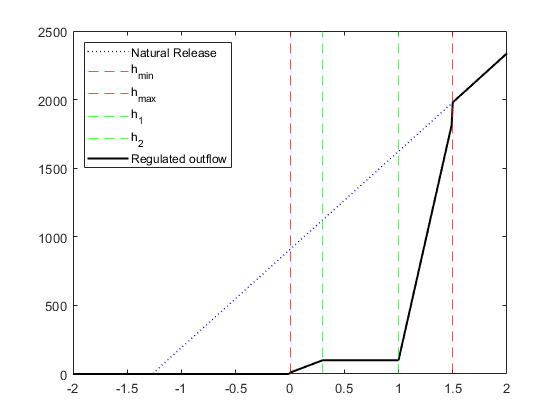

param.reg.w = w;
param.reg.hmin = 0;
param.reg.hmax = 1.5;

param.nat.S = lake_surface;
param.nat.h0 = -1.27; % TODO: Check this param
% Add equation
param.nat.m = max_nat_release_est/(param.reg.hmax - param.nat.h0);
param.nat.b = -param.nat.m*param.nat.h0;

param.reg.h1 = 0.3;
param.reg.h2 = 1.0;

param.reg.m1 = 300;
param.reg.m2 = 3500;

h_test = -2:0.01:2;
r_test = zeros(size(h_test));
idx = find(h_test>param.nat.h0);
r_test(idx) = param.nat.m*h_test(idx) + param.nat.b;

r_reg = getRegulatedReleaseSimplified(h_test, param);

figure;
plot(h_test, r_test, ':b','LineWidth',1)
hold on;
xline(param.reg.hmin,'--r');
xline(param.reg.hmax,'--r');

xline(param.reg.h1,'--g');
xline(param.reg.h2,'--g');

plot(h_test, r_reg,'k','LineWidth',1.5)
legend('Natural Release', 'h_{min}', 'h_{max}', 'h_1', 'h_2','Regulated outflow','Location','northwest')

### Trajectories Alternative-0 vs SOP

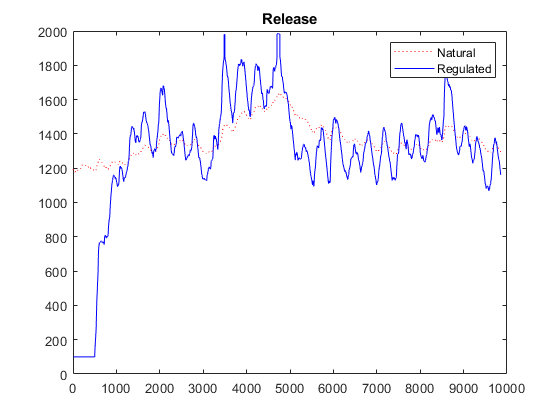

h_init = 0.4;
h_bar = 1.5; % Flooding thereshold

[r_reg, s_reg, h_reg] = simRegLakeSimplified(h_init, data_streamflow, param);
[r_nat, s_nat, h_nat] = simNatLakeSimplified(h_init, data_streamflow, param);

figure; 
plot (r_nat, ':r');
hold on; 
plot(r_reg,'b'); 
title('Release');legend('Natural','Regulated');

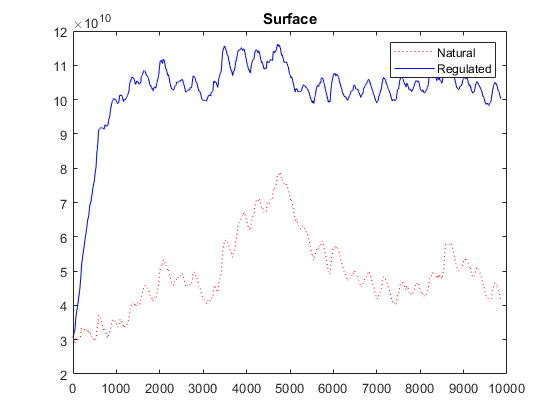

figure;
plot (s_nat, ':r');
hold on; 
plot(s_reg, 'b');
title('Surface');legend('Natural','Regulated');

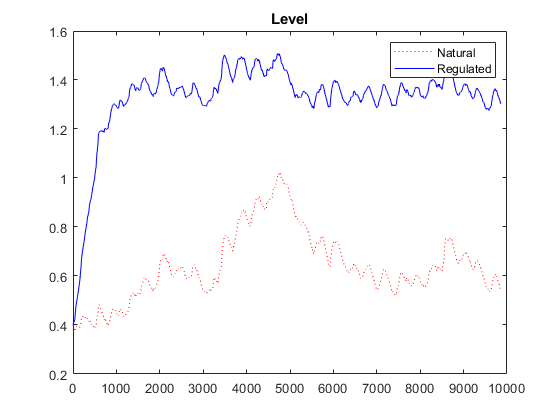

figure; 
plot (h_nat, ':r');
hold on;
plot(h_reg, 'b');
title('Level');legend('Natural','Regulated');

### Indicators

#### Reliability

I_rel_sop = getReliability(r_reg, w)

I_rel_sop = 0.9999

I_rel_nat = getReliability(r_nat, w)

I_rel_nat = 0.9999

#### Flooding 1

I_f1 = getFlooding1(h_reg,h_bar,years_total)

I_f1 = 3.1111